
syms x y
u(x,y) = sin(3*x)*sin(1-x)*(y-1)*tan(y)

$$u(x, y) = -\sin\left(3\,x\right)\,\sin\left(x-1\right)\,\tan\left(y\right)\,\left(y-1\right)$$

f = -diff(u,x,2) -diff(u,y,2)

$$f(x, y) = \begin{array}{l} 2\,\sin\left(3\,x\right)\,\sin\left(x-1\right)\,\sigma_{1}+6\,\cos\left(3\,x\right)\,\cos\left(x-1\right)\,\tan\left(y\right)\,\left(y-1\right)-10\,\sin\left(3\,x\right)\,\sin\left(x-1\right)\,\tan\left(y\right)\,\left(y-1\right)+2\,\sin\left(3\,x\right)\,\sin\left(x-1\right)\,\tan\left(y\right)\,\sigma_{1}\,\left(y-1\right)\\ \mathrm{where}\\ \sigma_{1}={\tan\left(y\right)}^{2}+1 \end{array}$$

g0 = 0

g0 = 0

gy = diff(u,y)

$$gy(x, y) = -\sin\left(3\,x\right)\,\sin\left(x-1\right)\,\tan\left(y\right)-\sin\left(3\,x\right)\,\sin\left(x-1\right)\,\left({\tan\left(y\right)}^{2}+1\right)\,\left(y-1\right)$$

gx = diff(u,x)

$$gx(x, y) = -3\,\cos\left(3\,x\right)\,\sin\left(x-1\right)\,\tan\left(y\right)\,\left(y-1\right)-\cos\left(x-1\right)\,\sin\left(3\,x\right)\,\tan\left(y\right)\,\left(y-1\right)$$

a1 = subs(gy, y, 1)

$$a1(x, y) = -\sin\left(3\,x\right)\,\sin\left(x-1\right)\,\tan\left(1\right)$$

a2 = subs(-gy, y,0)

$$a2(x, y) = -\sin\left(3\,x\right)\,\sin\left(x-1\right)$$

a3 = subs(gx,y, 1)

$$a3(x, y) = 0$$

%plot 3d
[X,Y] = meshgrid(0:0.01:1,0:0.01:1);
Z = sin(3*X).*sin(1-X).*(Y-1).*tan(Y);

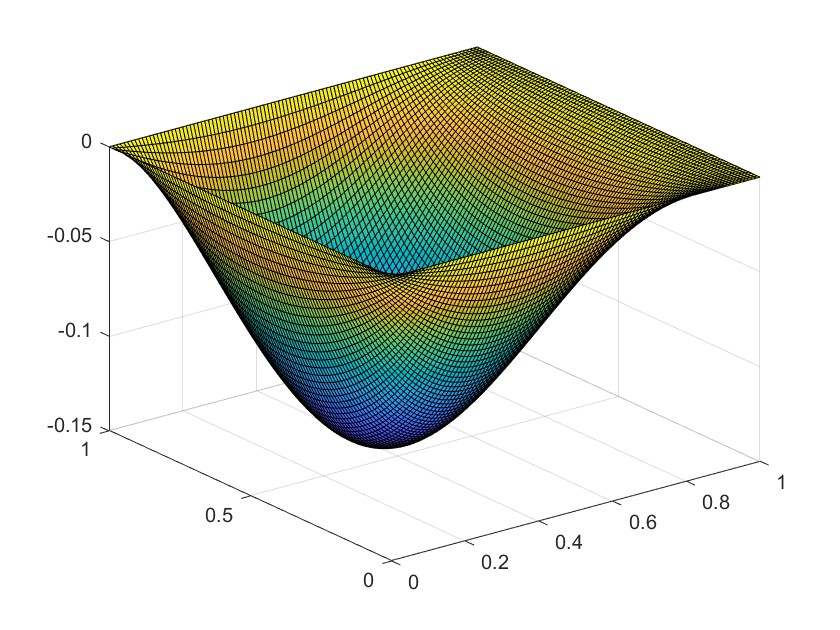

surf(X,Y,Z)